# Get Whisker Contacts from Trace

From function getContactTimes. Reads ntrode trace of contact signal and calculates times and indices of contact onsets. Requires various manually selected thresholds. Livescript version might help with plotting.

Adapted from Amanda's getContactTimes_wholetrace_timesOnly.m

Read in ntrode file

fpath = 'D:\Data\GP09-7\160607-001\';
nfile = '160607-00';
samplingRate = 16000;
dt = 1000/samplingRate;
stimDur = 1500;

contacts = readNtrode(fpath,nfile,{'top_contact','bot_contact','trial_start'});
rawContactTop = contacts.top_contact;
rawContactBottom = contacts.bot_contact;
totalTime = length(rawContactTop)*dt;
trialStartSig = contacts.trial_start;
trialStartTimes = getEventTimes(trialStartSig, samplingRate,'negative');

Plot whole trace for top and bottom contacts

j = figure;
h = figure;

figure(j)
hold on
plot(dt:dt:length(rawContactTop)*dt,rawContactTop,'r')
axis tight
title('top contact signal')
xlabel('time (ms)')

figure(h)
hold on
plot(dt:dt:length(rawContactBottom)*dt,rawContactBottom,'r')
axis tight
title('bottom contact signal')
xlabel('time (ms)')

Select a range of trials to plot a smaller amount of data

firstTrialTop = 50;
stopTrialTop = 65;
firstTrialBottom = 50;
stopTrialBottom =  65;

Plot the data between those trials

startPlotTop = trialStartTimes(firstTrialTop);
startPlotTop = startPlotTop/dt;
endPlotTop = trialStartTimes(stopTrialTop);
endPlotTop = endPlotTop/dt;

startPlotBottom = trialStartTimes(firstTrialBottom);
startPlotBottom = startPlotBottom/dt;
endPlotBottom = trialStartTimes(stopTrialBottom);
endPlotBottom = endPlotBottom/dt;

figure
plot(dt:dt:length(rawContactTop(startPlotTop:endPlotTop))*dt,rawContactTop(startPlotTop:endPlotTop),'r')
hold on
axis tight
title(['top contact signal, trials ' num2str(firstTrialTop) ' to ' num2str(stopTrialTop)])
xlabel('time (ms)')

figure
plot(dt:dt:length(rawContactBottom(startPlotBottom:endPlotBottom))*dt,rawContactBottom(startPlotBottom:endPlotBottom),'r')
hold on
axis tight
title(['bottom contact signal, trials ' num2str(firstTrialBottom) ' to ' num2str(stopTrialBottom)])
xlabel('time (ms)')

Band-pass filtering data to get rid of high-frequency electrical noise and low frequency baseline shifts

cutoffFreq = [20 3000];
cfreq = cutoffFreq/samplingRate;
[b,a] = butter(1,[cfreq],'bandpass');
filtContactTop = filtfilt(b,a,rawContactTop);
filtContactBottom = filtfilt(b,a,rawContactBottom);

Plot filtered contact trace over raw contact trace

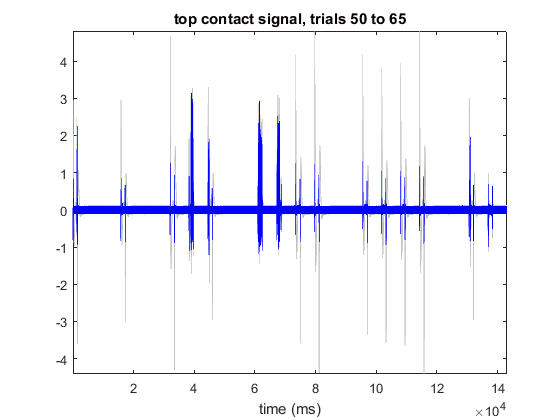

figure
plot(dt:dt:length(rawContactTop(startPlotTop:endPlotTop))*dt,rawContactTop(startPlotTop:endPlotTop),'Color',[192/255,192/255,192/255])
hold on
plot(dt:dt:length(filtContactTop(startPlotTop:endPlotTop))*dt,filtContactTop(startPlotTop:endPlotTop),'b')
axis tight
title(['top contact signal, trials ' num2str(firstTrialBottom) ' to ' num2str(stopTrialBottom)])
xlabel('time (ms)')

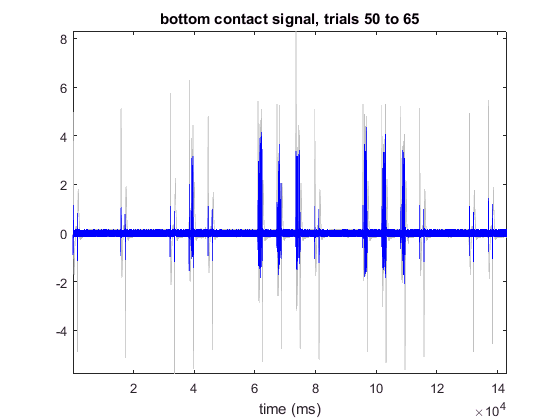


figure
plot(dt:dt:length(rawContactBottom(startPlotBottom:endPlotBottom))*dt,rawContactBottom(startPlotBottom:endPlotBottom),'Color',[192/255,192/255,192/255])
hold on
plot(dt:dt:length(filtContactBottom(startPlotBottom:endPlotBottom))*dt,filtContactBottom(startPlotBottom:endPlotBottom),'b')
axis tight
title(['bottom contact signal, trials ' num2str(firstTrialBottom) ' to ' num2str(stopTrialBottom)])
xlabel('time (ms)')

Cut out motor artefact

motorCutTop = [170, 100];
preMotorTop = 100;
motorCutBottom = [170, 110];
preMotorBottom = 100;
contactTop = cutoutNoise(filtContactTop,trialStartTimes,dt,motorCutTop(1)); %cut out around motor moving into position (at trial start times)
contactTop = cutoutNoise(filtContactTop,trialStartTimes+stimDur-preMotorTop,dt,motorCutTop(2)); %cut out around motor moving out of position (at end of stim dur)
contactBottom = cutoutNoise(filtContactBottom,trialStartTimes,dt,motorCutBottom(1));
contactBottom = cutoutNoise(filtContactBottom,trialStartTimes+stimDur-preMotorBottom,dt,motorCutBottom(2));

Plot cut contact (green) signal over filtered contact signal (blue) over raw contact signal (gray)

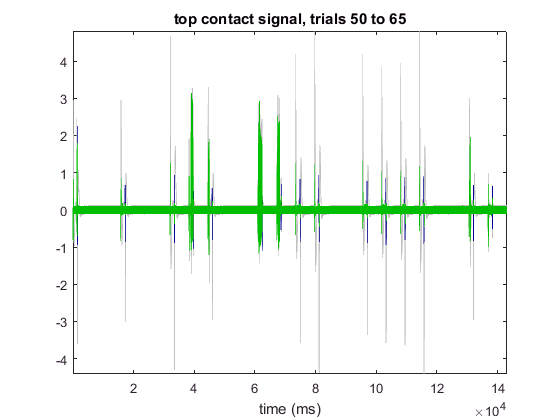

figure
plot(dt:dt:length(rawContactTop(startPlotTop:endPlotTop))*dt,rawContactTop(startPlotTop:endPlotTop),'Color',[192/255,192/255,192/255])
hold on
plot(dt:dt:length(filtContactTop(startPlotTop:endPlotTop))*dt,filtContactTop(startPlotTop:endPlotTop),'Color',[0,0,145/255])
plot(dt:dt:length(contactTop(startPlotTop:endPlotTop))*dt,contactTop(startPlotTop:endPlotTop),'Color',[0,190/255,0])
axis tight
title(['top contact signal, trials ' num2str(firstTrialBottom) ' to ' num2str(stopTrialBottom)])
xlabel('time (ms)')

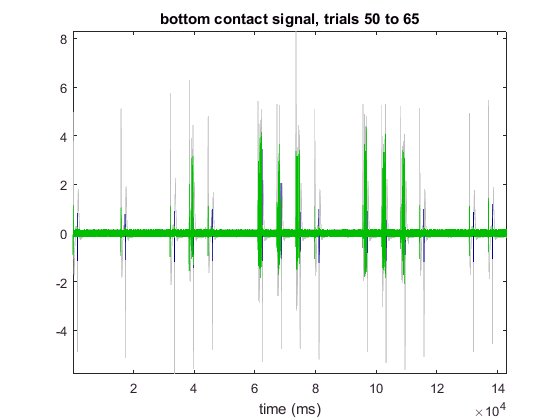


figure
plot(dt:dt:length(rawContactBottom(startPlotBottom:endPlotBottom))*dt,rawContactBottom(startPlotBottom:endPlotBottom),'Color',[192/255,192/255,192/255])
hold on
plot(dt:dt:length(filtContactBottom(startPlotBottom:endPlotBottom))*dt,filtContactBottom(startPlotBottom:endPlotBottom),'Color',[0,0,145/255])
plot(dt:dt:length(contactBottom(startPlotBottom:endPlotBottom))*dt,contactBottom(startPlotBottom:endPlotBottom),'Color',[0,190/255,0])
axis tight
title(['bottom contact signal, trials ' num2str(firstTrialBottom) ' to ' num2str(stopTrialBottom)])
xlabel('time (ms)')

Select a threshold for contacts and plot it over the figure

threshTop = .7;
threshBottom = .7;

figure
plot(dt:dt:length(rawContactTop(startPlotTop:endPlotTop))*dt,rawContactTop(startPlotTop:endPlotTop),'Color',[192/255,192/255,192/255])
hold on
plot(dt:dt:length(filtContactTop(startPlotTop:endPlotTop))*dt,filtContactTop(startPlotTop:endPlotTop),'Color',[0,0,145/255])
plot(dt:dt:length(ContactTop(startPlotTop:endPlotTop))*dt,ContactTop(startPlotTop:endPlotTop),'g')
axis tight
title(['top contact signal, trials ' num2str(firstTrialBottom) ' to ' num2str(stopTrialBottom)])
xlabel('time (ms)')
line([0 length(contactTop(startPlotTop:endPlotTop))*dt],[threshTop threshTop],'LineStyle','--','Color','m')

figure
plot(dt:dt:length(rawContactBottom(startPlotBottom:endPlotBottom))*dt,rawContactBottom(startPlotBottom:endPlotBottom),'Color',[192/255,192/255,192/255])
hold on
plot(dt:dt:length(filtContactBottom(startPlotBottom:endPlotBottom))*dt,filtContactBottom(startPlotBottom:endPlotBottom),'Color',[0,0,145/255])
plot(dt:dt:length(filtContactBottom(startPlotBottom:endPlotBottom))*dt,filtContactBottom(startPlotBottom:endPlotBottom),'g')
axis tight
title(['bottom contact signal, trials ' num2str(firstTrialBottom) ' to ' num2str(stopTrialBottom)])
xlabel('time (ms)')
line([0 length(contactBottom(startPlotBottom:endPlotBottom))*dt],[threshBottom threshBottom],'LineStyle','--','Color','m')